# Read Foreign-Language Dates

Load the file `german_dates.txt` and preview its contents in a text editor. A screen shot is shown below. Notice that the first column of values contains dates in German and the second and third columns are numeric values.

filename = 'german_dates.txt';

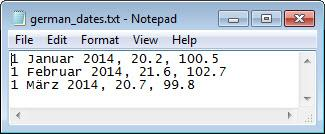

Open the file. Specify the character encoding scheme associated with the file as the last input to `fopen`.

fileID = fopen(filename,'r','n','ISO-8859-15');

Read the file. Specify the format of the dates in the file using the `%{dd % MMMM yyyy}D` specifier. Specify the locale of the dates using the `DateLocale` name-value pair argument.

C = textscan(fileID,'%{dd MMMM yyyy}D %f %f',...
    'DateLocale','de_DE','Delimiter',',');
fclose(fileID);

View the contents of the first cell in C. The dates display in the language MATLAB uses depending on your system locale.

C{1}

*Copyright 2012 The MathWorks, Inc.*